clc;
clear;
close all;

## 添加路径

addpath('plane wave\')
addpath('镜头\')

## 参数设置

# Gaussian Beam

lambda=647e-6;

beamAmp=1;

color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, 'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
colormap(mymap)

# MLA

rate=(0.15/40);%采样率（global）
rla1=-1.1;% 透镜1的曲率半径  
N=10:1:80;%微透镜单元采样点数
d = N*rate;% 透镜单元边长
focallen=75/0.15.*d;
beamSize=3/0.15*d;



beamStd=beamSize/2.85;
num=max(beamStd)./d*5;%数量
area1 = mean(num.*d);%光场的面积
n=round(area1/rate);
t = 1.2;%透镜厚度
material={"F_SILICA"};
area3=20;
distance1 = 1;   % 投影距离

# Diffuser

rpm=50000;%电机转速(圈每分钟)
rpus=rpm/60/1000/1000;
radius_diffuser=22;%散射片半径mm
velocity=2*pi*rpus*radius_diffuser;%线速度
deltat=n*0.033*rate/velocity;%
T=100;%积分时间（μs）
times=floor(T/deltat);
route=velocity*T;
if route>2*pi*radius_diffuser
    route=2*pi*radius_diffuser;
    T=route/velocity;
    times=floor(T/deltat);
end
diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);
phase=Diffuser.generateDiffuser(diffuser,rate,[round(route/rate)+n,n]);


Diffuser.diffuserSingle(diffuser)
rate= single(rate);
lambda= single(lambda);
area1= single(area1);
area3= single(area3);

if canUseGPU
    
    Diffuser.diffuserGPUArray(diffuser)
    rate= gpuArray(rate);
    lambda= gpuArray(lambda);
    area1= gpuArray(area1);
    area3= gpuArray(area3);
end


u=zeros(1,length(rla1));
sigma=u;
fn=u;
B=u;


for jj=1:length(d)
beam=GaussianBeam(beamAmp,beamStd(jj),lambda);
beams=GaussianBeam.defocused(beam,10,n,rate);
MLA1=Lens([rla1,inf],t,d(jj),material,lambda);
MLA2=Lens([inf,-rla1],t,d(jj),material,lambda);

# Fourier Lens


distance=[20,distance1,focallen(jj),focallen(jj)];
area2=adapWin(rate,lambda,focallen(jj));
area=[area1,area1,area2,area3];
Dfl = area2;              %采样区域
FL=Lens(focallen(jj));
%% 生成傅里叶透镜厚度函数
Lens.lensPhase_paraxial(FL,Dfl,rate,lambda)
Lens.lensSingle(FL);
%%生成匀光微透镜阵列厚度函数
Lens.lensArrayThickFcn(MLA1,N(jj),num(jj),'square');
Lens.lensArrayThickFcn(MLA2,N(jj),num(jj),'square');

Lens.lensSingle(MLA1)
Lens.lensSingle(MLA2)
if canUseGPU
    Lens.lensGPUArray(MLA1)
    Lens.lensGPUArray(MLA2)
    Lens.lensGPUArray(FL)
end

I=zeros(round(area3/rate));

lensgroup={MLA1,MLA2,FL};

## 光场变换

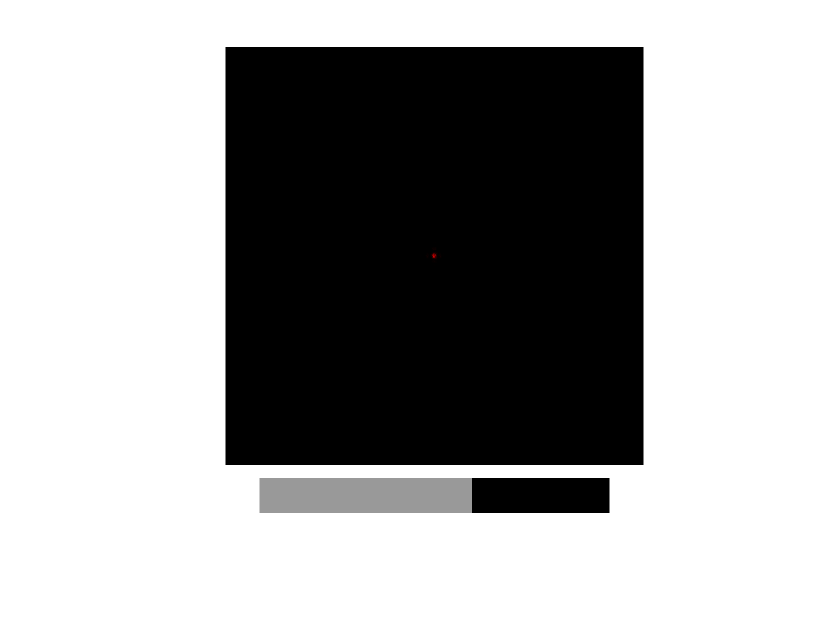

tic
for ii=1:times
    %叠加随机相位
    beamss=GaussianBeam.beamNoise(beams,0.05,0);
    F = transform(beamss, area1, lambda, 20, [rate, rate]);
    
    index=round((velocity*(ii-1)*deltat)/rate+1);
    F=F.*phase(index:index+size(F,1)-1,:);
    F=ASMlensgroup(F,lensgroup,distance,area,lambda,rate);

    I_now=abs(F).^2;
    I = I+I_now;

    Inorm=imnorm(I);
    subplot(11,10,[1,90])
    imshow(uint16(Inorm*65536),mymap)
    
    Inorm=gather(Inorm);

    subplot(11,10,[91,100])
    progressBar([100,1000],ii/times)
    drawnow
end


subplot(11,10,101:110)
progressBar([100,1000],jj/length(d))
[u(jj),sigma(jj)]=homoanalyse(Inorm);
fn(jj)=fresnelnum(MLA1,lambda);
B(jj)=beamStd(jj)/d(jj);
end

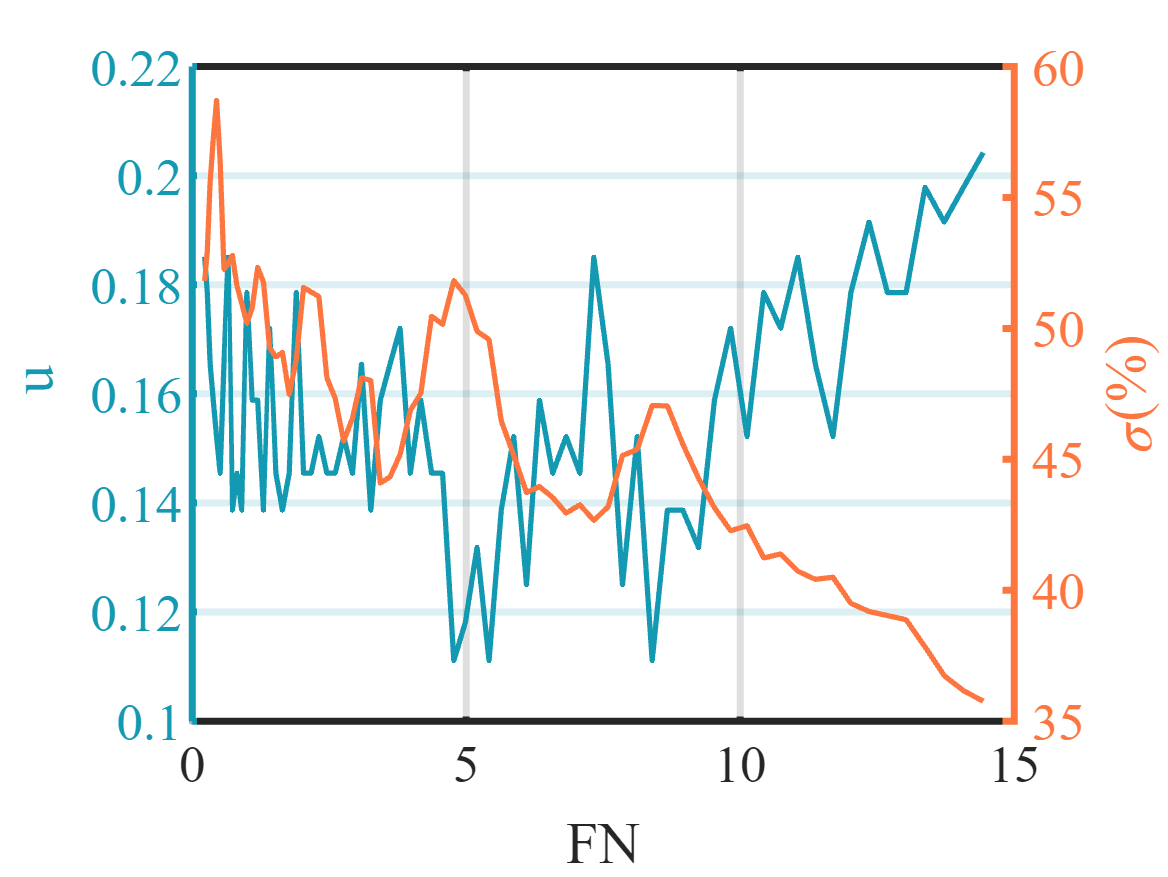

load('E:\File\Matlab\资料\color_2.mat');

figure
colororder([color5;color6])
yyaxis left
plot(fn(1:jj),u(1:jj),'LineWidth',1.5)
ylabel('\it u')
yyaxis right
plot(fn(1:jj),sigma(1:jj),'LineWidth',1.5)
set(gca,'LineWidth',2,'fontname','Times New Roman','Fontsize',15)
xlabel('FN')
ylabel('\sigma(%)')
grid on